# Bird migration modelling: Inference

This MATLAB livescript presents a spatio-temporal model of the nocturnal migration of birds over Europe based on measurement of weather radars. 

The model decomposes a power transform of the bird density $B$ [bird/km^2] at location$\mathit{\mathbf{s}}$ and time $t$ at at two scales: a multi-night and intra-night scale:

${B\left(t,\mathit{\mathbf{s}}\right)}^p =\underbrace{\mu \left(\mathit{\mathbf{s}}\right)+M\left(d\left(t\right),\mathit{\mathbf{s}}\right)} +\underbrace{\iota \left(t,\mathbf{s}\right)+I\left(t,\mathit{\mathbf{s}}\right)}$,

where $\mu \left(s\right)$ and is $\iota \left(t,\mathbf{s}\right)$ are determinisitic trend modeled with basis function (polynomial) accounting for the non-stationarity at the multi-night and intra-night scale respectively. $M\left(t,\mathit{\mathbf{s}}\right)$ and $I\left(t,\mathit{\mathbf{s}}\right)$ are random process at the multi-night  (i.e. the average density over the night),  and intra-night scale respectively. $d\left(t\right)$ maps the continous time $t$ the day of its closer night

## 1. Import and create data

clear all; load('../1-Cleaning/data/dc_corr.mat'); load coastlines;  addpath('./functions/'); warning('off')

Define a few useful variable

uniqueDate = round(datenum(datetime(start_date:end_date)))';
dclat = [dc.lat]';
dclon = [dc.lon]';

Create the data structure `data` used for the rest of the code

dens_lim = 0.002;
data=[];
t15min = bsxfun(@plus,datenum(start_date:1/24/60*15:end_date),(-4:4)'*1/24/60);
t15min = datetime(sort(t15min(:)),'ConvertFrom','datenum');

for i_d=1:numel(dc)
    id = dc(i_d).NNT(:)>=-1 & dc(i_d).NNT(:)<=1 & dc(i_d).denss>dens_lim & ismember(dc(i_d).time,t15min);
    d=table();
    d.dens=dc(i_d).denss(id);
    d.NNT = dc(i_d).NNT(id)';
    d.radar=i_d*ones(sum(id),1);
    d.lat=dc(i_d).lat*ones(sum(id),1);
    d.lon=dc(i_d).lon*ones(sum(id),1);
    d.time = datenum(dc(i_d).time(id));
    % d.duration = dc(i_d).etime(id)-dc(i_d).stime(id);
    [~,d.day]=ismember(round(datenum(dc(i_d).sunrise(id)))',uniqueDate);
    d.dayradar = sub2ind([numel(dc) numel(uniqueDate)],d.radar, d.day);
    % filter by day with less than 10% of data present
    tmp3 = [uniqueDate,histc(uniqueDate(d.day),uniqueDate)];
    tmp4 = ~ismember(uniqueDate(d.day),tmp3(0.1*max(tmp3(:,2))>tmp3(:,2),1));
    data = [data ; d(tmp4,:) ];
end

Define the covaraince function used

Gneiting = @(dist,time,range_dist,range_time,delta,gamma,beta) 1./( (time./range_time).^(2.*delta) +1 ) .* exp(-(dist./range_dist).^(2.*gamma)./((time./range_time).^(2.*delta) +1).^(beta.*gamma) );

Delete variable not used

clear d dens_lim tmp* id

## 2. Power transformation $p$

Bird densities present a very skew histogram

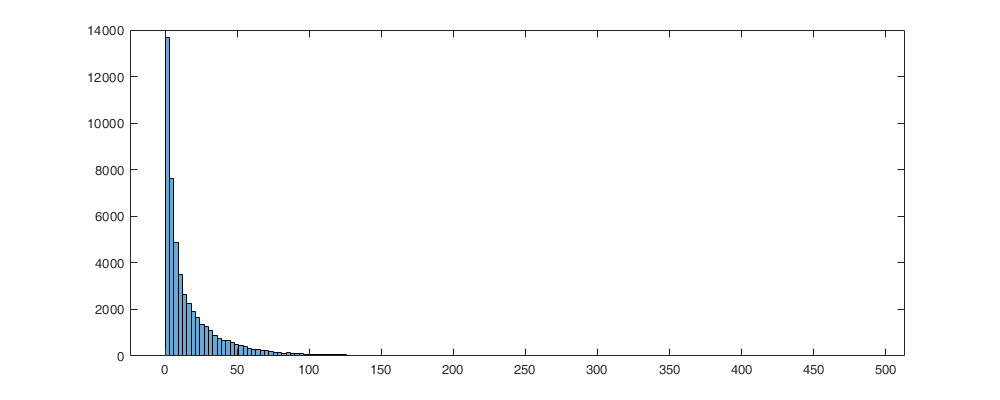

figure('position',[0 0 1000 400]); histogram(data.dens)

We fit a power transformation $p$ on $\mathrm{Z}\left(t,\mathit{\mathbf{s}}\right)$ by minimizing the [Kolmogorov-Smirnov test](https://en.wikipedia.org/wiki/Kolmogorov%E2%80%93Smirnov_test) of the transformed variable ${\mathrm{Z}\left(t,\mathit{\mathbf{s}}\right)}^p$

tmp = @(data,parm) data.^parm;
pow = fminsearch(@(parm) kstestmin(data.dens,tmp,parm), 1/8);
disp(['Power transformation p: ' num2str(pow)]);

Power transformation p: 0.13271


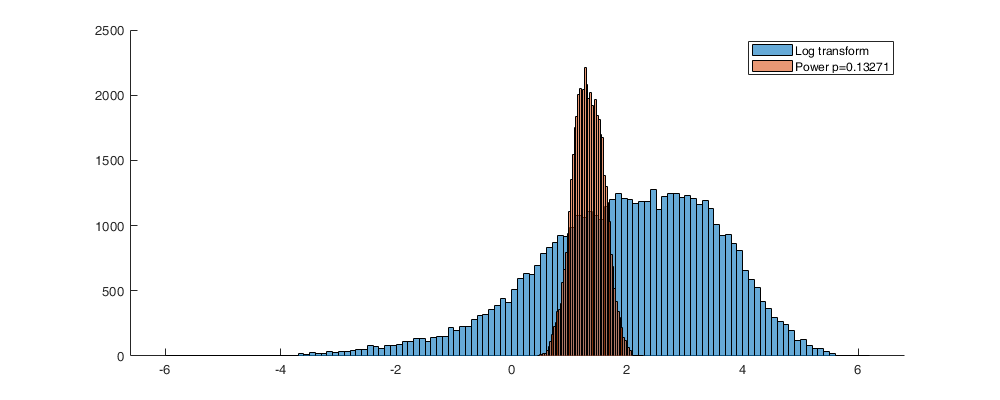


figure('position',[0 0 1000 400]); hold on;
histogram(log(data.dens))
histogram(data.dens.^pow)
legend('Log transform',['Power p=' num2str(pow)])

The transformed densities will be modeled

data.denst = data.dens.^pow;

## 3. Multi-night scale

The multi-night scale considers the daily (or nightly) fluctuation of bird density. The average bird density over night is modeled as a Gaussian process $M$ with a spatial trend $\mu$. 

Define the structure `multi` as with the grid data day * radar:

multi.t = uniqueDate;
multi.r = 1:69;
[multi.T,multi.R]=meshgrid(multi.t,multi.r);

Compute the the multi-night scale at all day*radar as the average during this night. Note that in the code we note `multi.M` for $\mu +M$ and `multi.Mn` for $M$.

multi.M=nan(numel(dc), numel(uniqueDate));
for i_d=1:numel(multi.M)
    multi.M(i_d)=mean(data.denst(data.dayradar==i_d));
end
multi.isnan=isnan(multi.M);

### 3.1 Spatial trend $\mu \left(s\right)$

The spatial trend accounts for the smoothly variation of the multi-scale Only the latitude component is fitted as adding the latitude shows little improvment. 


$$\mu \left(s\right)=w_0 +w_{\textrm{lat}} s_{\textrm{lat}}$$


Compute the parameters of the trend

multi.w = [ones(sum(~multi.isnan(:)),1) dclat(multi.R(~multi.isnan))] \ multi.M(~multi.isnan);
fprintf('Spatial trend parameters w_0=%.3f, w_{lat}=%.3f',multi.w(1),multi.w(2));

Spatial trend parameters w_0=2.566, w_{lat}=-0.024

Illustration of the spatial trend

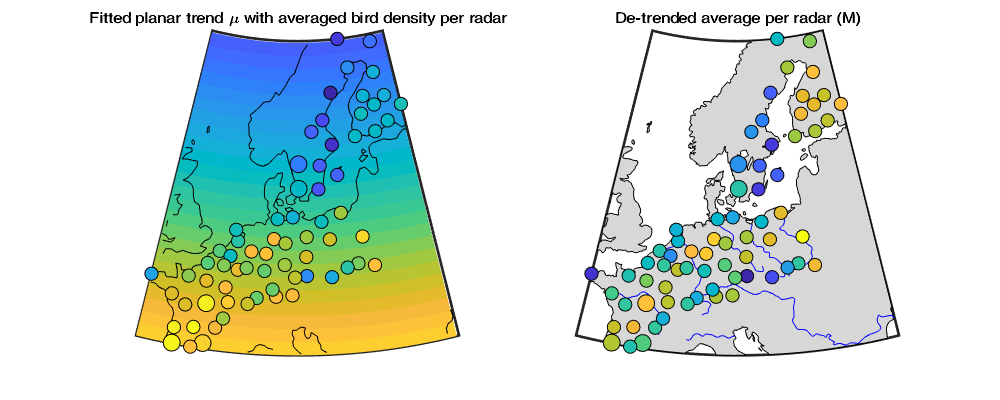

figure('position',[0 0 1000 400]);  
subplot(1,2,1); hold on; h=worldmap([min(dclat) max(dclat)], [min(dclon) max(dclon)]);  
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
[LAT,LON] = meshgrid(min(dclat):max(dclat),min(dclon):max(dclon));
surfm(LAT,LON,LAT*multi.w(2)+multi.w(1))
plotm(coastlat, coastlon,'k')
scatterm(dclat,dclon,[dc.maxrange]*4,nanmean(multi.M,2),'filled','MarkerEdgeColor','k'); 
title('Fitted planar trend \mu with averaged bird density per radar'); 

subplot(1,2,2); hold on; h=worldmap([min(dclat) max(dclat)], [min(dclon) max(dclon)]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')
scatterm(dclat,dclon,[dc.maxrange]*4,nanmean(multi.M,2)-dclat*multi.w(2)-multi.w(1),'filled','MarkerEdgeColor','k'); title('De-trended average per radar (M)');

The average of each radar during the study period shows a strong NS increase (left). The residual (right) shows more the coridor of migration with lower migration density along the FR-NL coast, and along the Alps. Another strange effect is the drastic change between Sweden and Finland. 

Compute the de-trended amplitude

multi.Mn = (multi.M(~multi.isnan)-dclat(multi.R(~multi.isnan))*multi.w(2)-multi.w(1));

Check histogram

%figure('position',[0 0 1000 400]); hold on;  histogram(ampli.An); histogram(ampli.A);

### 3.2 Covariance function of $M\left(t,\mathbf{s}\right)$

Buliding the distance matrix in time and space of the amplitude

Dtime=squareform(pdist(multi.T(~multi.isnan)));
Ddist=squareform(pdist([dclat(multi.R(~multi.isnan)) dclon(multi.R(~multi.isnan))],@lldistkm));

Compute the empirical covariance on a grid

multi.cov.emp = bsxfun(@times, multi.Mn', multi.Mn);

multi.cov.d=[0 1 300 500 1000];
multi.cov.t=[0 1 2 3 5 10]; 
[multi.cov.D,multi.cov.T] = meshgrid(multi.cov.d(1:end-1)+diff(multi.cov.d)/2,multi.cov.t(1:end-1));
multi.cov.D_emp=nan(size(multi.cov.D)); multi.cov.T_emp = multi.cov.D_emp; 
multi.cov.emp_grid=nan(size(multi.cov.D));
for i_t=1:numel(multi.cov.t)-1
    for i_d=1:numel(multi.cov.d)-1
        id = Dtime>=multi.cov.t(i_t) & Dtime<multi.cov.t(i_t+1) & Ddist>=multi.cov.d(i_d) & Ddist<multi.cov.d(i_d+1);
        multi.cov.D_emp(i_t,i_d) = nanmean(Ddist(id)); multi.cov.T_emp(i_t,i_d) = nanmean(Dtime(id));
        multi.cov.emp_grid(i_t,i_d) = nanmean( multi.cov.emp(id) );
    end
end
%figure;surf(ampli.cov.D_emp,ampli.cov.T_emp,ampli.cov.emp_grid); xlabel('Distance [km]'); ylabel('Time [days]')

The covariance function is fitted with a nugget and a Gneiting model. The data are filtered by a maximum distance and time in order to reduce the computational cost and overfitting long-distance/time lag. 

Gneiting_fit = @(parm) parm(1)*(multi.cov.D_emp==0 & multi.cov.T_emp==0) + parm(2)*(multi.cov.D_emp==0) + parm(3).*Gneiting(multi.cov.D_emp,multi.cov.T_emp,parm(4),parm(5),parm(6),parm(7),parm(8));

multi.cov.parm0 =[.5 .5 .5 500 5 .5 .5 .5 ];
multi.cov.parm_min=[0 0 0 0.0001 0 0 0 0 ]';
multi.cov.parm_max=[nancov(multi.Mn) nancov(multi.Mn) nancov(multi.Mn) 3000 10 1 1 1 ]';

rmse = @(parm) sum(sum(  ( 1000*abs(multi.cov.emp_grid).*abs(Gneiting_fit(parm) - multi.cov.emp_grid) ) ));
multi.cov.parm = fmincon(rmse,multi.cov.parm0,[],[],[1 1 1 0 0 0 0 0],nancov(multi.Mn),multi.cov.parm_min,multi.cov.parm_max,[],optimoptions('fmincon','Display','off'));

Construct the covariance function as inline function.

multi.cov.C = @(D,T) multi.cov.parm(1)*(D==0 & T==0) + multi.cov.parm(2)*(D==0) + multi.cov.parm(3).*Gneiting(D,T,multi.cov.parm(4),multi.cov.parm(5),multi.cov.parm(6),multi.cov.parm(7),multi.cov.parm(8));

Shows the resultings paramters

fprintf(['nugget(0,0)\t nugget(0,:)\t var\t range distance[km]\t range time[day]\t shape distance (delta)\t shape time (gamma)\t separability (beta)\n%.3f\t\t %.3f\t\t %.3f\t %.3f\t\t %.3f\t\t\t %.3f\t\t\t %.3f\t\t\t %.3f'],multi.cov.parm)

nugget(0,0)	 nugget(0,:)	 var	 range distance[km]	 range time[day]	 shape distance (delta)	 shape time (gamma)	 separability (beta)
0.001		 0.006		 0.032	 500.023		 1.124			 0.979			 0.708			 0.095

Illustration of the fitted covariance function

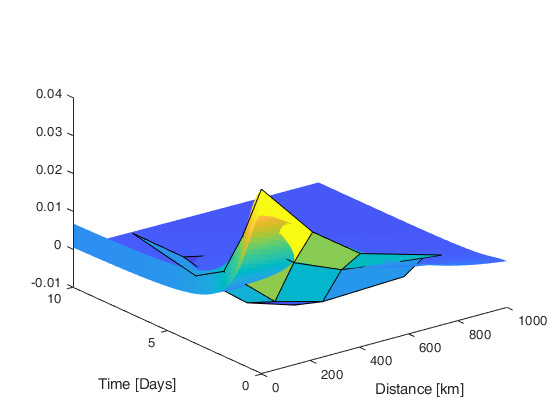

[tmpD,tmpT] = meshgrid(multi.cov.d(1):1:multi.cov.d(end),multi.cov.t(1):0.1:multi.cov.t(end));
figure; hold on;
s=surf(tmpD,tmpT,multi.cov.C(tmpD, tmpT));
surf(multi.cov.D_emp,multi.cov.T_emp,multi.cov.emp_grid);  xlabel('Distance [km]'); ylabel('Time [Days]');
s.EdgeColor='none'; view(3);

## 4. Intra-night scale

At the intra-night scale, we model the the fluctuation around the multi-night scale

intra.I = data.denst-multi.M(data.dayradar);

### 4.1 Curve trend $\iota \left(t,\mathbf{s}\right)$

The most important trend at the intra-night scale is along the the night. We use a polynomial function to account for this smooth variation


$$\iota \left(t,\mathit{\mathbf{s}}\right)=\sum_{i=i}^8 a_i \textrm{NNT}\left(t,\mathit{\mathbf{s}}\right)$$


intra.apo=8;
intra.a = bsxfun(@power,data.NNT,0:intra.apo)\intra.I;
disp('Polynomial coefficient a: ');fprintf('%.2f, ',intra.a);

Polynomial coefficient a: 
0.04, -0.10, 0.07, 0.27, -1.29, -0.59, 2.86, 0.44, -1.92, 

Ilustration

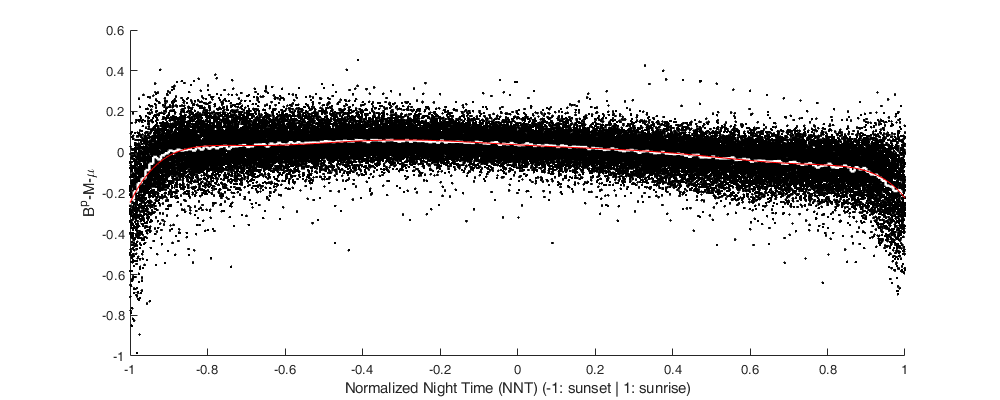

NNT_axis=-1:.01:1;
[~,id] = min(bsxfun(@minus,data.NNT,NNT_axis).^2,[],2);
figure('position',[0 0 1000 400]); hold on; 
plot(data.NNT,intra.I,'.k');
stairs(NNT_axis-diff(NNT_axis(1:2)),splitapply(@nanmean,intra.I,id),'w','linewidth',2)
plot(NNT_axis, bsxfun(@power,NNT_axis',0:intra.apo)*intra.a,'-r');  
xlabel('Normalized Night Time (NNT) (-1: sunset | 1: sunrise)'); ylabel('B^p-M-\mu'); ylim([-1 .6]); xlim([-1 1])

In addition to present a trend of the mean, the intra-night components also contains a non-stationarity of variance along the night (see figure below). We fit another polynomial function to normalize the variance


$$\sigma_I \left(t,\mathit{\mathbf{s}}\right)=\sum_{i=i}^{10} b_i \textrm{NNT}\left(t,\mathit{\mathbf{s}}\right)$$


intra.bpo=10;
intra.b = bsxfun(@power,data.NNT,0:intra.bpo) \ (intra.I-bsxfun(@power,data.NNT,0:intra.apo)*intra.a).^2;
disp('Polynomial coefficient b');fprintf('%.2f, ',intra.b)

Polynomial coefficient b
0.00, -0.00, 0.02, 0.04, -0.17, -0.17, 0.62, 0.26, -0.93, -0.12, 0.49, 

Illustration

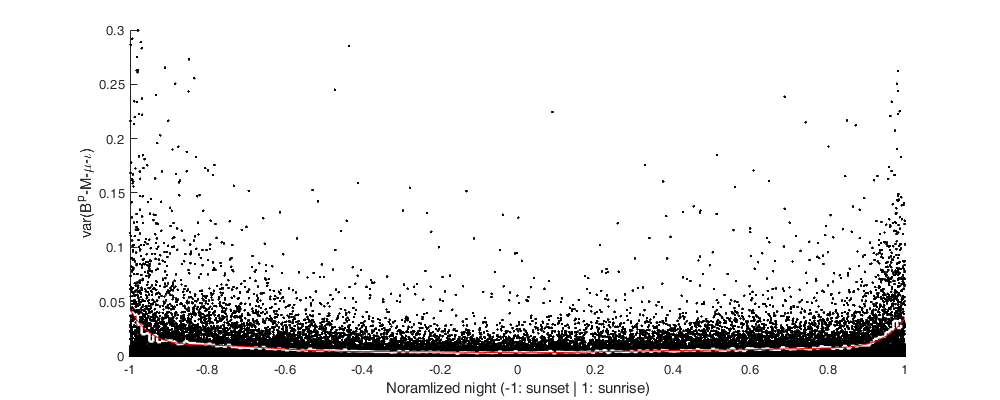

figure('position',[0 0 1000 400]); hold on;
plot(data.NNT,(intra.I-bsxfun(@power,data.NNT,0:intra.apo)*intra.a).^2,'.k');
stairs(NNT_axis-diff(NNT_axis(1:2)),splitapply(@nanmean,(intra.I-bsxfun(@power,data.NNT,0:intra.apo)*intra.a).^2,id),'w','linewidth',2)
plot(NNT_axis, bsxfun(@power,NNT_axis',0:intra.bpo)*intra.b,'-r');
xlabel('Noramlized night (-1: sunset | 1: sunrise)'); ylabel('var(B^p-M-\mu-\iota)');ylim([0 .3]); xlim([-1 1])

Finally, combining the polynomial of the curve and the correction for variance, we find the de-trended intra-night scale $I$

intra.In = (intra.I-bsxfun(@power,data.NNT,0:intra.apo)*intra.a) ./ sqrt(bsxfun(@power,data.NNT,0:intra.bpo)*intra.b);

Check the histogram

% figure('position',[0 0 1000 400]); histogram(res.Rn);xlim([-6 6])

### 4.2 Covariance function of $I\left(t,\mathit{\mathbf{s}}\right)$

Built the matrix of distances of the data. Distence (or difference) in lattitude, longitude, time and value. 

Ddist_sm = squareform(pdist([dclat dclon], @lldistkm));

D=table(); 
for i_t=1:numel(multi.t)
    id = find(data.day==i_t);
    d= table();
    d.Ddist = reshape(Ddist_sm(data.radar(id),data.radar(id)),[],1);
    d.Dtime = reshape(squareform(pdist(data.time(id))),[],1);
    d.Did1 = repmat(id,numel(id),1);
    d.Did2 = repelem(id,numel(id));
    A = ones(numel(id));
    B = tril(A);
    D=[D ; d(B(:)==1,:)];
end

Empirical covariance function

intra.cov.d=[0 1 100 150 200 250 300 600 1000];
intra.cov.t=[0 .01 .02 .05 .07 .1 .5]; 
[intra.cov.D,intra.cov.T]=meshgrid(intra.cov.d(1:end-1)+diff(intra.cov.d)/2,intra.cov.t(1:end-1)+diff(intra.cov.t)/2);
intra.cov.D_emp=nan(size(intra.cov.D)); intra.cov.T_emp=nan(size(intra.cov.D));
intra.cov.emp_grid=nan(size(intra.cov.D));

for i_d=1:numel(intra.cov.d)-1
    id1 = find(D.Ddist>=intra.cov.d(i_d) & D.Ddist<intra.cov.d(i_d+1));
    for i_t=1:numel(intra.cov.t)-1
        id2 = id1(D.Dtime(id1)>=intra.cov.t(i_t) & D.Dtime(id1)<intra.cov.t(i_t+1));
        intra.cov.emp_grid(i_t,i_d)= mean(intra.In(D.Did1(id2)) .* intra.In(D.Did2(id2)));
        intra.cov.D_emp(i_t,i_d) = nanmean(D.Ddist(id2)); 
        intra.cov.T_emp(i_t,i_d) = nanmean(D.Dtime(id2));
    end
end
% figure; surf(res.cov.D_emp,res.cov.T_emp,res.cov.emp_grid);  xlabel('Distance [km]'); ylabel('Time [Days]');

Calibrate the covariance function 

Gneiting_fit = @(parm) parm(1)*(intra.cov.D_emp==0 & intra.cov.T_emp==0) + parm(2)*(intra.cov.D_emp==0) + parm(3).*Gneiting(intra.cov.D_emp,intra.cov.T_emp,parm(4),parm(5),parm(6),parm(7),parm(8));

intra.cov.parm0 =[.5 .5 .5 500 5 .5 .5 .5 ];
intra.cov.parm_min=[0 0 0 0.0001 0 0 0 0 ]';
intra.cov.parm_max=[nancov(intra.In) nancov(intra.In) nancov(intra.In) 3000 10 1 1 1 ]';

rmse = @(parm) sum(sum(  ( 1000*abs(intra.cov.emp_grid).*abs(Gneiting_fit(parm) - intra.cov.emp_grid) ) ));
intra.cov.parm = fmincon(rmse,intra.cov.parm0,[],[],[1 1 1 0 0 0 0 0],[nancov(intra.In)],intra.cov.parm_min,intra.cov.parm_max,[],optimoptions('fmincon','Display','off'));

Build the inline covariance function.

intra.cov.C = @(D,T) intra.cov.parm(1)*(D==0 & T==0) + intra.cov.parm(2)*(D==0) + intra.cov.parm(3).*Gneiting(D,T,intra.cov.parm(4),intra.cov.parm(5),intra.cov.parm(6),intra.cov.parm(7),intra.cov.parm(8));

Display the parameters values.

fprintf(['nugget(0,0)\t nugget(0,:)\t var\t range distance[km]\t range time[day]\t shape distance (delta)\t shape time (gamma)\t separability (beta)\n%.3f\t\t %.3f\t\t %.3f\t %.3f\t\t %.3f\t\t\t %.3f\t\t\t %.3f\t\t\t %.3f'],intra.cov.parm)

nugget(0,0)	 nugget(0,:)	 var	 range distance[km]	 range time[day]	 shape distance (delta)	 shape time (gamma)	 separability (beta)
0.089		 0.000		 0.913	 190.241		 0.066			 1.000			 0.403			 0.999

Figure

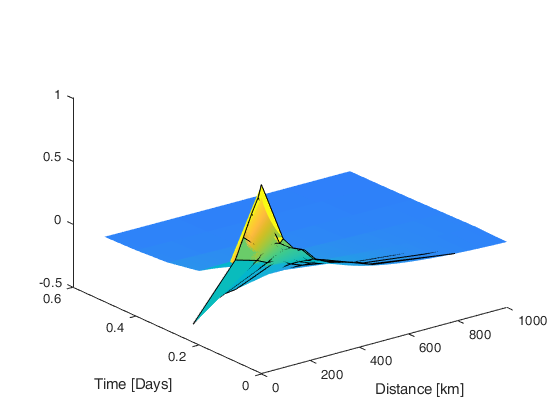

[tmpD,tmpT] = meshgrid(intra.cov.d(1):1:intra.cov.d(end),intra.cov.t(1):0.1:intra.cov.t(end));
figure; hold on;
s=surf(tmpD,tmpT,intra.cov.C(tmpD,tmpT));
surf(intra.cov.D_emp,intra.cov.T_emp,intra.cov.emp_grid);  xlabel('Distance [km]'); ylabel('Time [Days]');
s.EdgeColor='none'; view(3)

## 5. Save

Save the parameters of the model. 

save('data/Density_inference.mat','data','multi','intra','pow','-v7.3')
% writetable(data,'data/Density_data.csv')

## 6. Model quality (bonus)

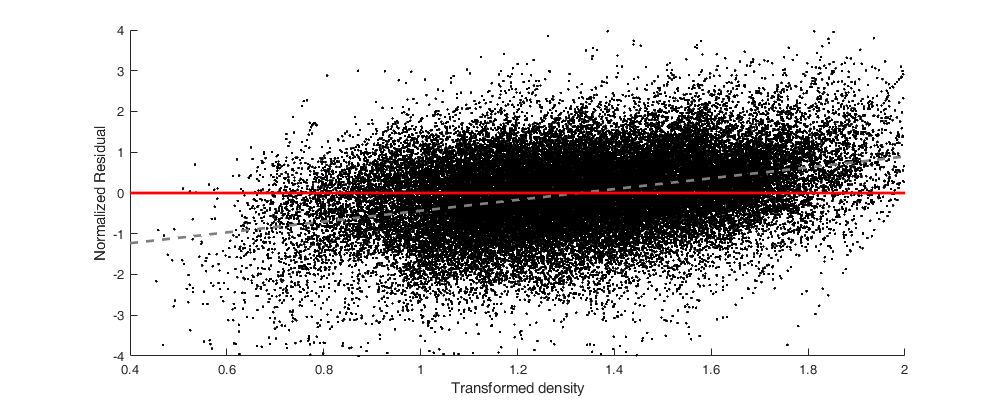

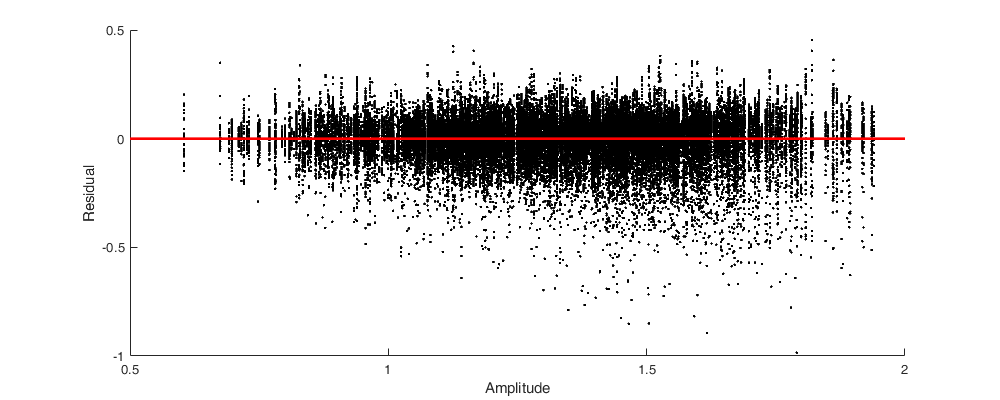

figure('position',[0 0 1000 400]); hold on; ylabel('Normalized Residual'); xlabel('Transformed density')
scatter(data.denst,intra.In,'.k'); 
coeffs = [ones(size(data.denst)) data.denst] \ intra.In;
plot( [.2 2.2],[1 .2;1 2.2]*coeffs,'--','Color',[.5 .5 .5],'LineWidth',2)
plot([.2 2.2],[0 0],'r','LineWidth',2); axis([.4 2 -4 4])
figure('position',[0 0 1000 400]); hold on; ylabel('Residual'); xlabel('Amplitude')
scatter(multi.M(data.dayradar),intra.I,'.k'); 
coeffs = [ones(size(data.dayradar)) multi.M(data.dayradar)] \ intra.I;
plot( [.5 2],[.5 1;2 1]*coeffs,'--','Color',[.5 .5 .5],'LineWidth',2)
plot([.5 2],[0 0],'r','LineWidth',2);
for i_r=1:numel(dc)
    res_r_m(i_r)=mean(intra.In(data.radar==i_r));
    res_r_std(i_r)=std(intra.In(data.radar==i_r));
end
figure('position',[0 0 1000 400]);
subplot(1,2,1); hold on; worldmap([min(dclat) max(dclat)], [min(dclon) max(dclon)]);  
plotm(coastlat, coastlon,'k')
scatterm(dclat,dclon,[dc.maxrange]*4,res_r_m,'filled','MarkerEdgeColor','k'); title('Average Residual'); colorbar;

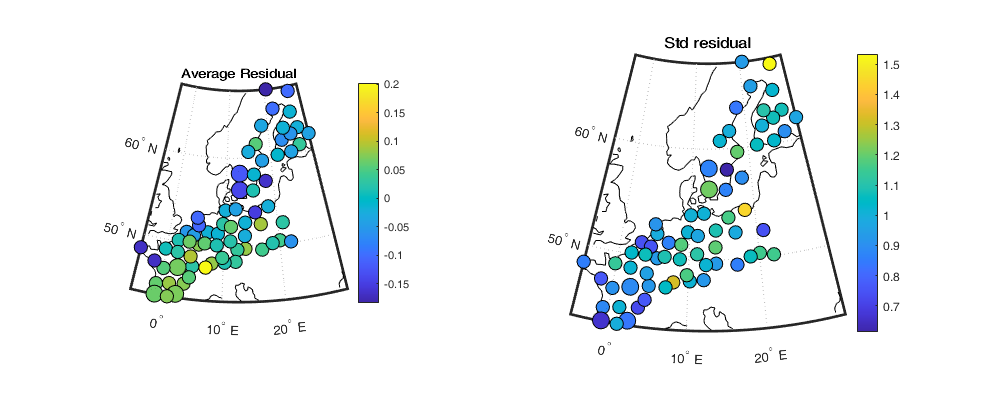

subplot(1,2,2); hold on; worldmap([min(dclat) max(dclat)], [min(dclon) max(dclon)]);  
plotm(coastlat, coastlon,'k')
scatterm(dclat,dclon,[dc.maxrange]*4,res_r_std,'filled','MarkerEdgeColor','k'); title('Std residual'); colorbar;